%% Load data & Formulate origin and fitting series in .txt
load("data\ComparedSOTA_Dataset.mat")
TourDate = 1:288;

TourDate =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


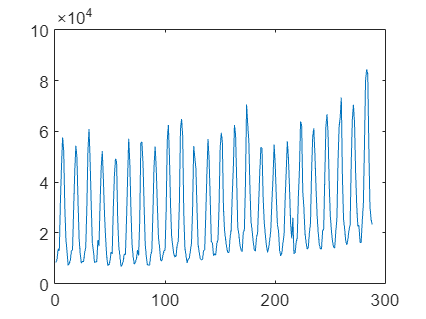

plot(TourDate,TourNum)

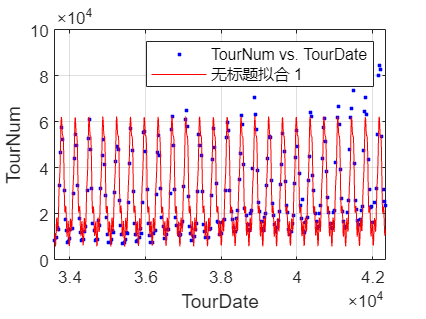

[xData, yData] = prepareCurveData( TourDate, TourNum );
ft = fittype( 'fourier6' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0 0 0 0 0 0 0 0 0 0 0 0 0 0.0172634742269388];
[fitresult, gof] = fit( xData, yData, ft, opts );
figure( 'Name', 'fourier6' );
h = plot( fitresult, xData, yData );
legend( h, 'TourNum vs. TourDate', 'fourier6', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'TourDate', 'Interpreter', 'none' );
ylabel( 'TourNum', 'Interpreter', 'none' );
grid on

y_fit = feval(fitresult, xData);
dlmwrite('X:\05_Data\pythonProject\DTW-LSTM\data\dataTourFit.txt', y_fit, 'delimiter', '\t', 'precision', 6);
dlmwrite('X:\05_Data\pythonProject\DTW-LSTM\data\dataTourNum.txt', TourNum, 'delimiter', '\t', 'precision', 6);

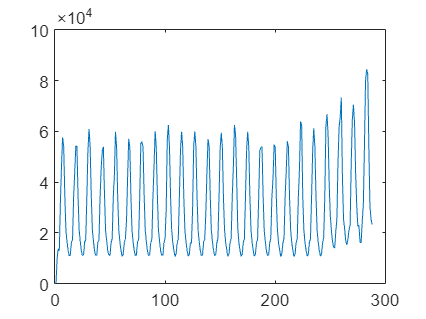

load("X:\05_Data\pythonProject\DTW-LSTM\result\processedTrainDataset_TourData.mat")
trainPercent = 7/8;
TrainLimit = 252;
delta = 36;
data = Processed;
for i = 1 : 36
    data(i + TrainLimit) = TourNum(i + TrainLimit);
end
for i = 246:252
    data(i) = TourNum(i);
end

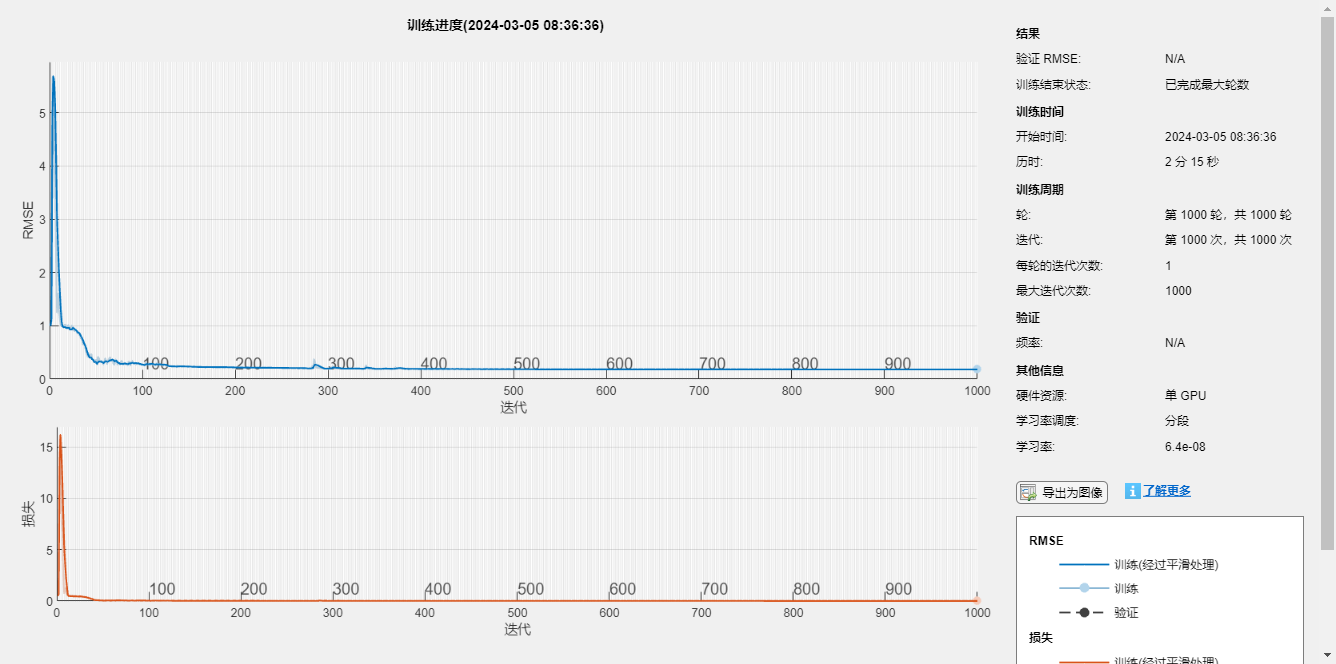

rmse = 1.0885e+04

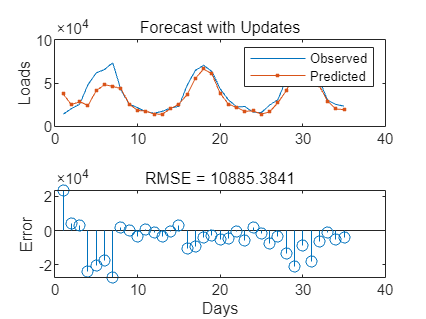

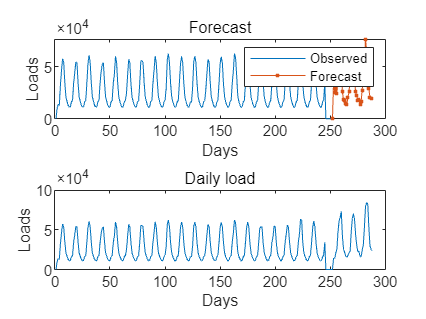

YPred = 0;
numTimeStepsTrain = floor(trainPercent*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 96*15;
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam', ...
    'MaxEpochs',1000, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
net = trainNetwork(XTrain,YTrain,layers,options);
net = resetState(net);
net = predictAndUpdateState(net,XTrain);
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
YTest = dataTest(2:end);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2))
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Loads")
title("Forecast with Updates")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)
figure
subplot(2,1,1)
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Days")
ylabel("Loads")
title("Forecast")
legend(["Observed" "Forecast"])
subplot(2,1,2)
plot(data)
xlabel("Days")
ylabel("Loads")
title("Daily load")

%% Alignment of the last errors may require manual action
for i = 1 : delta
    YReal(i) = data(i + TrainLimit);
end
YPred(delta) = YPred(delta - 1);


errors = YPred - YReal;
MAE = mean(abs(errors))

MAE = 1.0312e+04

SSE = sum(errors.^2)

SSE = 6.5605e+09

RMSE = sqrt(mean(errors.^2))

RMSE = 1.3499e+04

MAPE = mean(abs(errors) ./ max(abs(YReal), eps)) * 100

MAPE = 28.9726